close all
clear all

## Ex 2

### a)

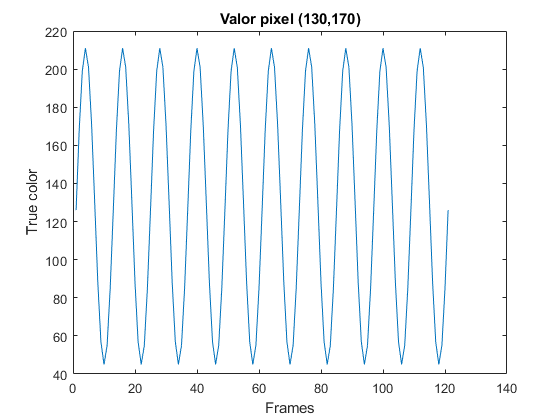

video = VideoReader('VP2023_Lab_1_Task_2.avi');      %leemos el video
a = 13;
b= 17;
x = zeros(1,121);           %creamos una matriz de zeros para añadir los nuevos valores y añadimos un frame mas para el 0 

for i = 1: 121
    frame = readFrame(video, 'native');
    x(i) = frame.cdata(10*a,10*b);        %cogemos la info del pixel que nos piden
end

%plot
figure(1)
plot(x)
title('Valor pixel (130,170)')
xlabel('Frames')
ylabel('True color')

#### Fouier

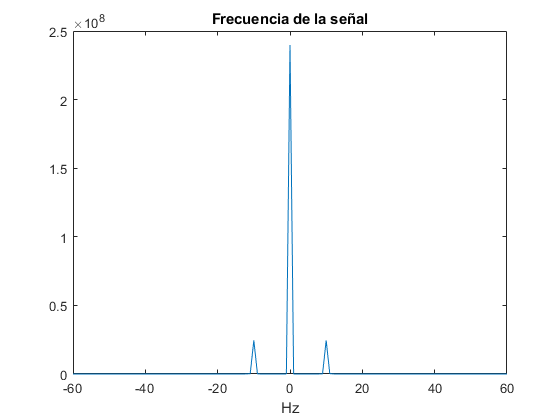

Fx = fft(x);            %calculamos la trans fourier
Fx = fftshift(Fx);      %centramos la señal

plot([-floor(length(x)/2) : floor(length(x)/2)] * 1, abs(Fx).^2) %multi por 1 pq es un seg
                                                                 %hacemos ^2 pq tiene parte imaginaria
                                                                 %energia de la señal evaluada en 0 
%Ft = 10 Hz
title('Frecuencia de la señal')
xlabel('Hz')

## 2c

% reader = VideoReader('VP2023_Lab_1_Task_2.avi');
% writer = VideoWriter('video_ex2c.avi');     %creamos un archivo para guardar el nuevo video
% writer.FrameRate = reader.FrameRate/2                    %el nuevo video tendra la mitad del fps que el original
% open(writer)                                %abrimos el archivo para empezar a grabar
% i=1;
% while hasFrame(reader)                      %bucle mientras exista un frame en el video original
%     frame = readFrame(video);               %leemos cada frame
%     img = frame;                            %cambiamos de unidad
%     if mod(i,2) == 0                        %cuando i sea par, osea obtendremos la mitad de frames
%         writeVideo(writer, img);            %guardamos el frame
%     end
%     i = i + 1;
% end
% close(writer)                               %cerramos el archivo para acabar de grabar